# Week 9 Homework: MECA 500 R3 Singularities

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

This week, we are asked to analyze the Mecademic 500 (R3) robot in terms of its singularities. Specifically, we are asked to do 6 things:

1) Construct the DH table for the robot in Matlab

2) Construct theJ in the matlab.

3) Decouple the J as needed to discuss the following singularities.

4) Discuss, prove, visualize, analyze, that Wrist singularity (at theta 5).

5) Discuss, prove, visualize, analyze Elbow singularity occurs when *θ*3 = −arctan(60/19) ≈ −72.43°.

6) Discuss, prove, visualize, analyze *shoulder singularity *occurs when the center of the robot wrist lies in the plane passing through the axes of joints 1 and 2.

### Approach:

The approach largely follows the six specific questions posed - First we construct the DH table for the Mecademic robot and realize it in MATLAB. Then from the DH table, the Jacobian is able to be calculated. From the Jacobian, we can decouple the wrist singularities from the arm singularities by splitting the Jacobian up into 3x3 upper left and 3x3 lower right submatricies. From these submatricies (and the Jacobian itself), we may confirm that an elbow sigularity occurs at the angle given for $\theta_3$. Finallly, we can show that when the wrist center aligns itself with the axes of joints 1 and 2, a singularity occurs. 

## Materials and Methods:

### General Background:

Robot singularities occur when there is a loss of a degree of freedom in terms of motion of the manipulator. This loss of a degree of freedom can be readily seen in the relationship between the individual joint velocities and the end effector velocity as expressed as


$$\chi =J\left(q\right)\dot{q}$$


where $\dot{q}$ is the individual joint velocity array, $\chi$ is the end effector velocity array and $J\left(q\right)$ is the Jacobian that relates the two. The Jacobian essentially maps or relates the individual joint linear and angular velocities to the end effector linear and angular velocity components. 

Indeed, $\chi$ is a 6x1 matrix, with 3 row elements describing the linear velocity in x,y and z. $\dot{q}$ is an nx1 column vector that contains the individual joint velocity. The Jacobian is therefore a 6xn matrix where n is the number of  joints on the manipulator. The 6 rows are the x,y and z mappings of linear velocity and the x,y, and z mappings of angular velocity from the individual joint angles to the end effector. 

The rank of a matrix is the number of linearly independent columns (or rows) in the matrix. When the rank of J =6, the end effector can execute any arbitrary velocity. For a matrix $J\in \Re^{6\textrm{xn}}$, it is always the case that rank $J\le \min \left(6,n\right)$. For example a 2-link planar arm will always have a rank of $J\le 2$ and a 6-DOF anthropomorphic arm will always have a rank $J\le 6$. This rank is dependent upon the configuration of the manipulator and is not constant. 

Singularties occur when a joint variable or joint variables take on values that results in a loss of rank in the Jacobian.  Configurations for which the rank of J(q) is less than maximum are called singular configurations. These represent configurations for which the manipulator either cannot attain, are at maximum reach of the manipulator or are unbounded at the end-effector in terms of velocity and force. 

The 2 major types of singularies are arm singularities and wrist singularies, if we are to consider at maximum a 6DoF manipulator consisting of a 3 link arm and a 3 link speherical wrist. Wrist singularities occur when any 2 revolute joints of a wrist are colinear, since an equal and opposite rotation about the axes results in no net motion at the end effector. 

Determining what these singular conditions are for typical manipulators is therefore of interest if we want to precisely control them. Doing so is fairly straightforward. We can exploit the fact that a square matrix is singular when its determinant is equal to 0. In general, solving $\textrm{det}\;J\left(q\right)=0$ is difficult. However, this problem can be greatly simplified by decoupling the singularities of a manipulator, which is applicable whenever the manipulator is equipped with a spherical wrist. 

If one supposes that the typical manipulator is a 6-link manipulator with a 3-link arm and a 3-link spherical wrist, it is possible to break the Jacobian of the manipulator up into 3x3 blocks as shown.

Because the final three joints are always revolute and the origins are always at the same location with a spherical wrist, the Jacobian has the form. Note that $J_{12}$ must be 0 for the decoupling of singularities to be possible:

With this in mind, the determinant of the Jacobian matrix is

Therefore, manipulator singular conditions occur if ${\textrm{det}\;J}_{11} \;\textrm{or}\;\textrm{det}\;J_{22} =0$. Determining the singular configurations for a manipulator is finding the joint variable values for which either of these determinants is made to equal 0. 

The two major types of singularites are arm singularities and wrist singularities. Wrist singularities occur when any 2 revolute joint axes are collinear with one another. In this configuration, equal and opposite rotation about the axes results in no net motion of the end-effector. This is the only singularity of the spherical wrist,and is unavoidable without imposing mechanical limits on the wrist design to restrict its motion in such a way that $z_3 \;\textrm{and}\;z_5$ are prevented from lining up. 

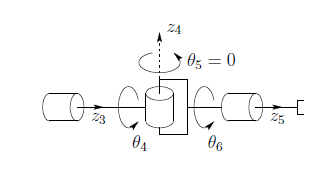

Arm singularies are entirely described by the determinant of $J_{11}$ and occur for 2 different conditions. One such configuration is where an arm is fully extended and is at maximum reach or is fully retracted. The other configuration is where the rotation axis of the base frame is aligned with the wrist center or end effector of a manipulator. The singular configurations for an articulated manipulator arm for this are shown to illustrate. 

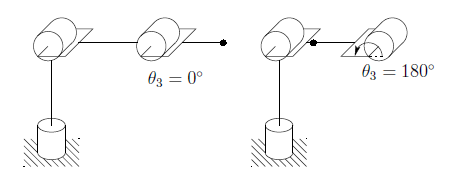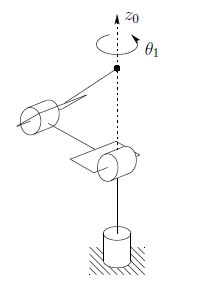

On the second case more specifically, it is precisely when $a_2 c_2 =-a_3 c_{23}$. For simplicity, if $a_2 =a_3$ then the singularity occurs when $c_2 =-c_{23}$, implying that the sum of $\theta_2 +\theta_3$ is exactly equal and opposite in sign from $\theta_2$. In this configuration, any rotation by $\theta_1$ yields no change in end effector position. 

### MECA 500 R3:

With this in mind, we can now begin analyzing the Mecademic 6DOF manipulator. 

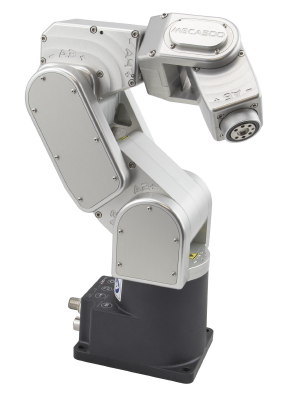

The Mecademic 500 R3 is a 6DoF robot consisting entirely of revolute joints. It is a remarkably small manipulator and is marketed as a tabletop robot. A dimensional drawing of the manipulator is shown below for reference

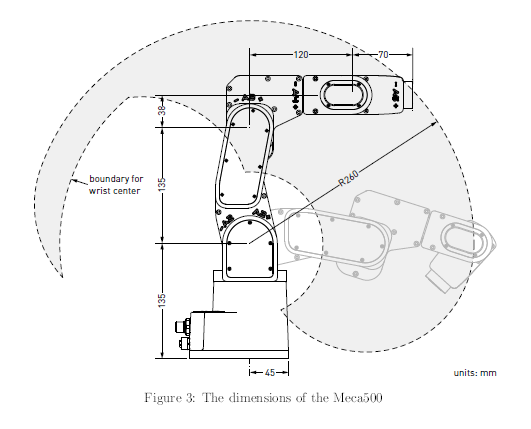

We may, by inspection of the robot, apply DH convention in order to obtain the manipulator's DH parameters. This yields the below diagram.

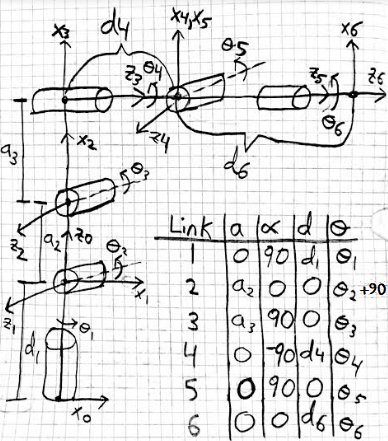

Additionally, I reached out to Mecademic for a DH parameter table for the Meca500 R3 and they provided me with the following:

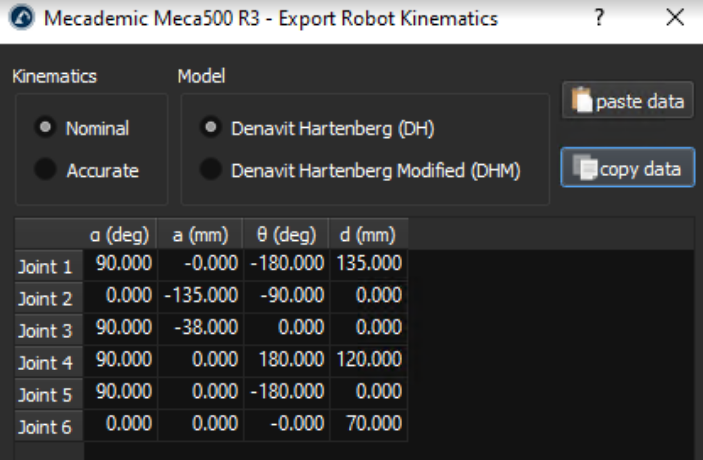

These parameters can be realized in MATLAB, **satisfying question 1**

syms 'a%d' 'alpha%d' 'd%d' 'theta%d' [1 6]

%Direct from Mecademic -  "the sure thing"
%d6 has been intentionally set to 0. 
% dh_table = [ 
%   0     pi/2    d1  -pi+theta1;
%   -a2    0       0   -pi/2+theta2;
%   -a3    pi/2    0   theta3;
%   0     pi/2   d4   theta4+pi;
%   0     pi/2    0   -pi+theta5;
%   0     0       0  theta6;]

%my own derivation as shown in the drawing
%running the code, appears to be *somewhat* equivalent to the Mecademic DH table
%d6 has been intentionally set to 0. 
dh_table = [ 
  0     pi/2    d1  theta1;
  a2    0       0   theta2+pi/2;
  a3    pi/2    0   theta3;
  0    -pi/2    d4  theta4;
  0     pi/2    0   theta5;
  0     0       0  theta6;]

$$dh\_table = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & d_{1} & \theta_{1}\\ a_{2} & 0 & 0 & \theta_{2}+\frac{\pi }{2}\\ a_{3} & \frac{\pi }{2} & 0 & \theta_{3}\\ 0 & -\frac{\pi }{2} & d_{4} & \theta_{4}\\ 0 & \frac{\pi }{2} & 0 & \theta_{5}\\ 0 & 0 & 0 & \theta_{6} \end{array}\right)$$




%use initialize function to set DH params into arrays
[a alpha d theta] = initialize_dh_params(dh_table, a,alpha, d, theta)

$$a = \left(\begin{array}{cccccc} 0 & a_{2} & a_{3} & 0 & 0 & 0 \end{array}\right)$$

$$alpha = \left(\begin{array}{cccccc} \frac{\pi }{2} & 0 & \frac{\pi }{2} & -\frac{\pi }{2} & \frac{\pi }{2} & 0 \end{array}\right)$$

$$d = \left(\begin{array}{cccccc} d_{1} & 0 & 0 & d_{4} & 0 & 0 \end{array}\right)$$

$$theta = \left(\begin{array}{cccccc} \theta_{1} & \theta_{2}+\frac{\pi }{2} & \theta_{3} & \theta_{4} & \theta_{5} & \theta_{6} \end{array}\right)$$

The construction of the Jacobian of the manipulator and the identification of singularities can now be undertaken.

## Results:   

With the `create_jacobian` function, we can pass in our dh parameters and a joint type array to construct the Jacobian for the Mecademic 500 R3

joint_types = ['r','r','r','r','r','r'];

Mecademic_Jacobian = simplify(create_jacobian(a,alpha,d,theta,joint_types))

### Decoupling Jacobian Singularities

The resulting Jacobian is a 6x6 matrix and **satisfies question 2. **The Jacobian of this manipulator a square 6x6 matrix, which means that it is of full rank and we can neatly take 2 submatricies, $J_{11}$ and $J_{22}$, the upper left 3x3 and the lower right 3x3 matrix, respectively. As described in the Materials and Methods section, we can take the determinant of both of these submatricies to obtain the arm and wrist singularities, respectively of the Mecademic 500, **satisfying question 3.**

%debug - prove that the singularites can be decoupled. J12 MUST be all 0's
J12 = subs(Mecademic_Jacobian(1:3,4:6))

$$J12 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


J11 = Mecademic_Jacobian(1:3,1:3); %upper left 3x3 for arm singularities
J22 = Mecademic_Jacobian(4:6,4:6); %lower right 3x3 for wrist singularities
%use singularity condition function 
[detJ11, detJ22] = getSingularityEqns(Mecademic_Jacobian)

$$detJ11 = \begin{array}{l} \frac{a_{2}\,{a_{3}}^{2}\,\cos\left(\theta_{2}\right)}{2}-\frac{{a_{2}}^{2}\,d_{4}\,\sin\left(\theta_{2}+\theta_{3}\right)}{2}-\frac{{a_{2}}^{2}\,a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)}{2}+\frac{a_{2}\,{d_{4}}^{2}\,\cos\left(\theta_{2}\right)}{2}+\frac{{a_{2}}^{2}\,a_{3}\,\cos\left(\theta_{2}-\theta_{3}\right)}{2}-\frac{a_{2}\,{a_{3}}^{2}\,\sigma_{1}}{2}+\frac{a_{2}\,{d_{4}}^{2}\,\sigma_{1}}{2}-\frac{{a_{2}}^{2}\,d_{4}\,\sin\left(\theta_{2}-\theta_{3}\right)}{2}-a_{2}\,a_{3}\,d_{4}\,\sin\left(\theta_{2}+2\,\theta_{3}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}+2\,\theta_{3}\right) \end{array}$$

$$detJ22 = -\sin\left(\theta_{5}\right)$$

### Wrist Singularity Condition by Inspection

At initial glance, the determinant of $J_{22}$ is simply $-\sin \left(\theta_5 \right)$, which yields the wrist singular condition described in the Materials and Methods and as shown below in the center pose for  when $\theta_5 =0$, **partially satisfying question 4**. 

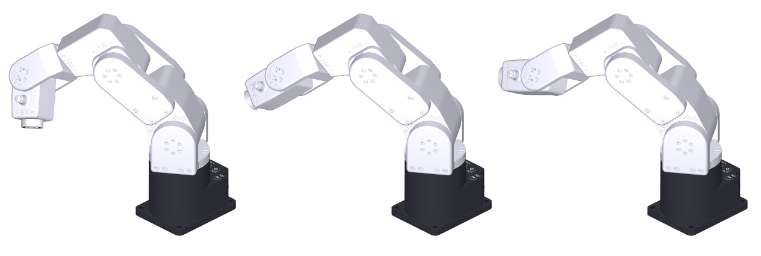

$\mathrm{det}\left(J_{11} \right)$ is considerably more complex and several specific conditions can cause it to be equal to zero.

### Elbow Singularity Calculation

The Mecademic documentation [here](https://www.mecademic.com/resources/Singularities/Robot-singularities) and the problem statement given describes an elbow singularity occuring when $\theta_3 \approx 72\ldotp {43}^{\circ }$. This visually is the robot in a "fully stretched out" pose as shown below in center. 

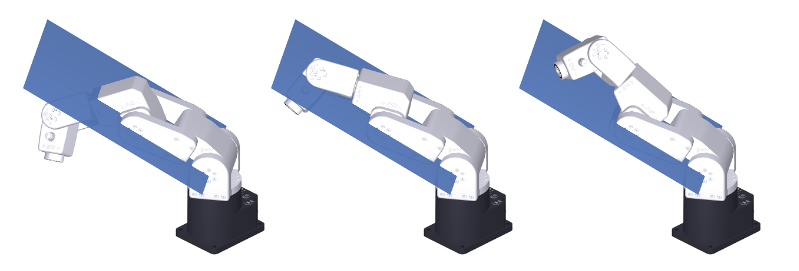 

We can numerically confirm this singularity condition by plugging in $\theta_3 =72\ldotp {43}^{\circ }$ to the expression $\textrm{det}\left(J_{11} \right)$.

%For good measure
syms 'theta%d' [1 6]

%singular condition we are asked to prove
%theta3 = -atan(60/19); %~72.43%

%plug in other values = 0
  theta1 = 0;
  theta2 = 0;
  theta4 = 0;
  theta5 = pi/4; 
  theta6 = 0;

%link dimensions (mm) - needed for this exercise
%negative dims for a2 a3 as per Mecademic
d1 = .135;
a2 = .135;
a3 = .038;
d4 = .120;
%d6 = .070;

%The resulting theta3 value for when det(J11) = 0
disp("Elbow singularity occurs at:")

Elbow singularity occurs at:


theta3solve = vpasolve(subs(detJ11)==0,theta3);
double(radtodeg(theta3solve))

ans = 72.4287

We are able to obtain the stated ~72.43 degree angle for $\theta_3$ when solving $\mathrm{det}\left(J_{11} \right)=0$ , which **partially answers question 5.**

### Shoulder Singularity Calculation

Continuing from the previous calculations, we can solve for an arm singularity by again setting $\textrm{det}\left(J_{11} \right)=0$ and solving for $\theta_1 ,\theta_2 \;\mathrm{and}{\;\theta }_3$ using `vpasolve` again to solve for our singularity conditions. 

A shoulder singularity for the Meca500 is shown below at center. 

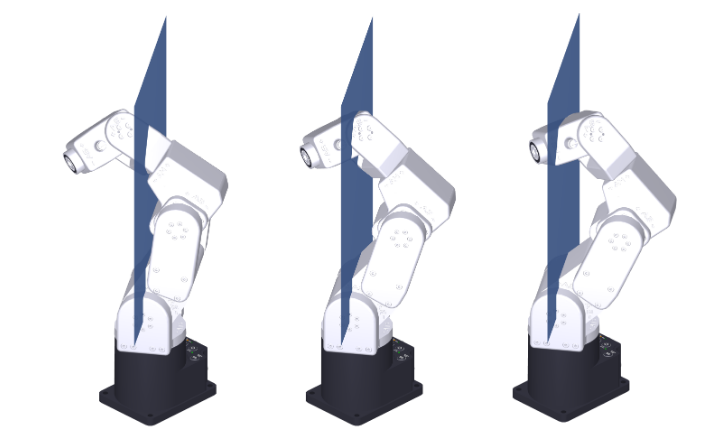

%Reset these values to symbolics for good measure
syms 'theta%d' [1 6]

theta2 = pi/4; theta4 = 0; theta5=pi/2; theta6=0;
s_singularityJ11 = simplify(subs(det(J11))) == 0;
[t1, t3] = vpasolve(s_singularityJ11, [theta1 theta3]);

%the resulting theta values solved for when det(J11)==0
disp("Shoulder singularity occurs at:")

Shoulder singularity occurs at:


disp("Theta1")

Theta1


rad2deg(double(t1))

ans = 0

disp("Theta2")

Theta2


rad2deg(double(theta2))

ans = 45

disp("Theta3")

Theta3


rad2deg(double(t3))

ans = -21.8928


%Sanity check that what is done below for the shoulder singularity
%visualization is an actual singular condition. 
theta3=t3;
theta2 = pi/4

theta2 = 0.7854

double(det(subs(s_singularityJ11)))

ans = 0

%adding 90deg to theta2 does NOT change the singularity
theta2 = (pi/2)+(pi/4)

theta2 = 2.3562

double(det(subs(s_singularityJ11)))

ans = 0

With this solution, we have determined a condition where a shoulder singularity can occur, **partially addressing question 6.**

### 3D-Visualizations of Singularities

With this done, we can model the robot  and its singularities using the Robotics Toolkit

%declare a RigidBodyTree object
mecademic = robotics.RigidBodyTree();

%give values to the DH params
theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = 0;
theta5 = 0;
theta6 = 0;
d1 = .135;
a2 = .135;
a3 = .038;
d4 = .120;
%d6 = .070;

%sub in values into dh table from M&M
dh_subbed = double(subs(dh_table))

dh_subbed =          0    1.5708    0.1350         0
    0.1350         0         0    1.5708
    0.0380    1.5708         0         0
         0   -1.5708    0.1200         0
         0    1.5708         0         0
         0         0         0         0


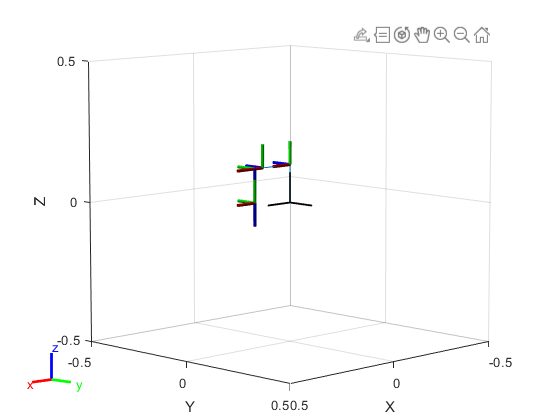

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%use homemade robot-generating function
construct_rigid_body_robot(mecademic,dh_subbed,joint_types);

config = homeConfiguration(mecademic);

With the robot generated we can set its configuration to be one of the singular conditons.

We can visualize the **elbow sigularity** obtained above **fully satisfying question 5**.

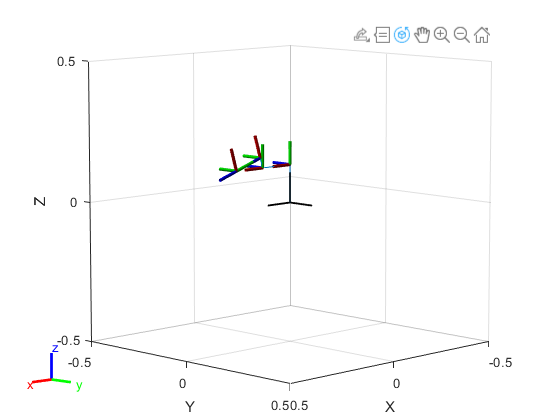

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


config(2).JointPosition = 0;
config(3).JointPosition = atan(60/19);
config(4).JointPosition = 0;
config(5).JointPosition = 0;
config(6).JointPosition = 0;
show(mecademic,config)

The **shoulder singularity** can be visualized, **fully satisfying question 6**.

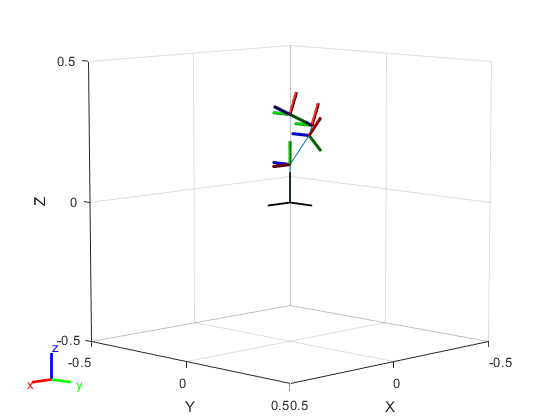

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


config(1).JointPosition =  double(t1);
config(2).JointPosition =  (pi/4)+(pi/2); 
%fascinating, had to add 90 to theta2 for the shoulder, 
% but sanity-check above checks out on
%the math. Perhaps hit on another singularity config?
config(3).JointPosition =  double(t3);
config(4).JointPosition = 0;
config(5).JointPosition = 0;
config(6).JointPosition = 0;
show(mecademic,config)

**Note:** In both figures above, **the wrist singularity is implicitly shown as **$\theta_5$** = 0 in both the elbow and the shoulder singularity poses**, which clearly sets the z axes for frames 4 and 6 colinear, **fully** **satisfying question 4**.

## Discussion:

This was the most challenging assignment thus far. Considerable effort went into modelling the Meca 500 R3 manipulator and its singular conditions. The assignment's results demonstrate singular conditions for the wrist, shoulder and elbow of the 6-link manipulator. In all 3 cases, we were able to calculate, demonstrate and visualize the singularities using MATLAB and  the Robotics toolbox.

Several discrepancies and areas for further work remain. Chief among them is figuring out why, with d6 being nonzero, that the singularity calculations and visualizations do not concur with the expected results. Omitting d6 (i.e. setting d6 to 0) yields the expected results. 

While my hand-derived DH parameters yield good results, they are slightly at odds with the manufacturer-provided DH table. I find that, for the calculation of the elbow singularity, that using the manufacturer provided DH table model yields -72.43 degrees while my self-derived DH table model yields 72.43 degrees. This is a minor difference in sign but may point to a larger discrepancy, as the shoulder singularity visualization when solving for $\theta_2 \;\mathrm{and}\;\theta_3$ did not meet expectations.

The visualization of the elbow singularity makes intuitive sense as it appears to be fully extended and the wrist center is in line with the elbow as shown in the Materials and Methods section and Spong et al. Similarly, the wrist singularity is relatively easy to demonstrate as only $\theta_5$ needs to be set to 0. It is implicitly and intentionally depicted in both elbow and shoulder singularity visualizations. 

Another discrepancy came when solving for the shoulder singularity. To make the visualization meet my expectation (with the wrist center lining up with the axis of rotation of the 1st link), I needed to add 90 degrees to $\theta_2$. Otherwise, the wrist center would line up with the x or  y-axis of the 1st link. I went back and plugged in the ammended value for $\theta_2$ into my $\mathrm{det}\left(J_{11} \right)$ expression along with my calculated value of $\theta_3$ and was able to get $\mathrm{det}\left(J_{11} \right)=0$, proving that despite the ammendment, that I had a legitimate singular condition. 

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- [Mecademic MECA 500 Programming Manual](https://www.mecademic.com/Documentation/Meca500-R3-Programming-Manual.pdf)

- [Mecademic Robot Singularity Tutorial](https://www.mecademic.com/resources/Singularities/Robot-singularities)

- [Meca 500 Users Manual](https://www.mecademic.com/Documentation/Meca500-R3-User-Manual.pdf)

- DH parameters gotten from Stan Gleizer, Sales and Technical Support Manager at Mecademic

## Defined Functions

function r_matrix = create_rotation_matrix(x, y, z)
    % This function creates a rotation matrix using roll (z), pitch (y),
    % and yaw (x) angles
    r_x_matrix = [1 0 0 ; 0 cos(x) -sin(x) ; 0 sin(x) cos(x)];
    r_y_matrix = [cos(y) 0 sin(y); 0 1 0; -sin(y) 0 cos(y)];
    r_z_matrix = [cos(z) -sin(z) 0; sin(z) cos(z) 0; 0 0 1];
    r_matrix = r_z_matrix * r_y_matrix * r_x_matrix;
end

function h_matrix = create_homogenous_matrix(x,y,z,dx,dy,dz)
    r_matrix = create_rotation_matrix(x,y,z);
    d_vector = [dx; dy; dz];
    h_matrix = [r_matrix d_vector; 0 0 0 1];
end

function dh_matrix = create_dh_matrix(a, alpha, d, theta)
    dh_matrix = [
      cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
      sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
      0,          sin(alpha),           cos(alpha),             d;
      0,            0,                  0,                      1];
end

function [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta)
    % This function creates several dh transformation matrices and
    % multiplies them together to give one final transformation matrix
    % Inputs are 1xn matrices representing the dh params for each link
    % Output is a 4x4 dh matrix representing the ovrall transform for all
    % given links
    
    % Find the umber of links by finding the length of the array theta
    number_of_links = size(theta,2);
    % Ensure that the arrays for alpha, a, and d are the same size as theta
    if (size(alpha,2)==number_of_links)&&(size(a,2)==number_of_links)&&(size(d,2)==number_of_links)
        
        % Start off by creating a symbolic dh matrix that is 4x4xn
        % Each 4x4 matrix will represent 1 step of the transform and there
        % will be n transforms for the n links
        A_i_array = sym("dh_matrix_array", [4,4,number_of_links]);
        
        % Initialize an identity matrix to calculate the ifinal dh
        % transform on the fly
        dh_intermediate_matrix = eye(4,4);
        for i=1:number_of_links
            dh_matrix = create_dh_matrix(a(i), alpha(i), d(i), theta(i)); % Create the dh matrix for link i
            A_i_array(:,:,i) = dh_matrix; % Assign that dh_matrix to our 4x4xn matrix at index i
            dh_intermediate_matrix = dh_intermediate_matrix * dh_matrix; % Get the full transform up to this point
            A_0_i_array(:,:,i) = dh_intermediate_matrix;
        end
        A_0_n = dh_intermediate_matrix;
    else
        disp("Error with array sizes of inputs");
        A_0_n = "ERROR";
    end
    % Below is code to replace certain variables in the symbolic matrix and
    % get an output
    %     create_dh_handle = matlabFunction(dh_final_matrix);
    %     y = feval(create_dh_handle, theta(1),theta(2),theta(3));
end

function p = PlotHAxes(H, l, linespec, color)
    % This function comes courtesy of John Dong (2019 RBE 500)
    
    % Plot a set of axes of length l represented by the given homogeneous transformation matrix
    p(1) = plot3([H(1,4) H(1,4)+H(1,1)*l], [H(2,4) H(2,4)+H(2,1)*l], [H(3,4) H(3,4)+H(3,1)*l], ...
        linespec, 'color', color);
    p(2) = plot3([H(1,4) H(1,4)+H(1,2)*l], [H(2,4) H(2,4)+H(2,2)*l], [H(3,4) H(3,4)+H(3,2)*l], ...
     linespec, 'color', color);
    p(3) = plot3([H(1,4) H(1,4)+H(1,3)*l], [H(2,4) H(2,4)+H(2,3)*l], [H(3,4) H(3,4)+H(3,3)*l], ...
     linespec, 'color', color);
end

function [a, alpha, d, theta] = initialize_dh_params(dh_table, a, alpha, d, theta)
    for i=1:size(dh_table,1)
        a(i) = dh_table(i,1);
        alpha(i) = dh_table(i,2);
        d(i) = dh_table(i,3);
        theta(i) = dh_table(i,4);
    end
end

function plot_links(A_0_i_array, figure_object, linespec, color, limits, labels, my_title)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    % limits: 3x2 array containing x, y, and z axis limits
    % labels: 3x1 array containing x, y, z axis labels
    % my_title: string title of graph
    figure_object;
    num_of_links = size(A_0_i_array,3);
    dx_array = NaN(1, num_of_links);
    dy_array = NaN(1, num_of_links);
    dz_array = NaN(1, num_of_links);
    for i=1:num_of_links
        dx_array(i) = A_0_i_array(1,4,i);
        dy_array(i) = A_0_i_array(2,4,i);
        dz_array(i) = A_0_i_array(3,4,i);
    end
    dx_array = [0 dx_array];
    dy_array = [0 dy_array];
    dz_array = [0 dz_array];
    plot3(dx_array, dy_array, dz_array, linespec, "color", color);
    xlim(limits(1,:));
    ylim(limits(2,:));
    zlim(limits(3,:));
    xlabel(labels(1));
    ylabel(labels(2));
    zlabel(labels(3));
    title(my_title)
    grid on
    
end

function plot_coordinate_frames(A_0_i_array, figure_object, l, linespec, color)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % l: length of the coordinate axis lines
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    num_of_links = size(A_0_i_array,3);
    figure_object;
    for i=1:num_of_links
        double(A_0_i_array(:,:,i));
        PlotHAxes(A_0_i_array(:,:,i), l, linespec, color);
    end
    grid on
   
end

function jacobian = create_jacobian(a, alpha, d, theta, joint_type)
    debug = false;
    error = false;
    % Inputs:
    % a: array of a values from dh table
    % alpha: array of alpha values from dh table
    % d: array of d values from dh table
    % theta: array of theta values from dh table
    % joint_type: array of string values.  Each is either "r" or "p" for
    % revolute or prismatic
    [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta);
    num_of_links = size(A_0_i_array,3);
    jacobian = sym("dh_matrix_array", [6,num_of_links]);
    o_n = simplify(A_0_i_array(1:3,4,num_of_links));
    for i=1:num_of_links
        % Create 1 column in the Jacobian for each link
        if i == 1
            z_i_minus1 = [0;0;1];
            o_i_minus1 = [0;0;0];
        else
            z_i_minus1 = A_0_i_array(1:3,3,i-1);
            o_i_minus1 = A_0_i_array(1:3,4,i-1);
        end
        
        if joint_type(i) == "r"
            o_difference = o_n-o_i_minus1;
            velocities = cross(z_i_minus1, o_difference);
            omega = z_i_minus1;
        elseif joint_type(i) == "p"
            velocities = z_i_minus1;
            omega = [0;0;0];
        else
            disp("Error with joint types")
            error = true;
        end
        if debug, jacobian(:,i), end
        if debug, [velocities; omega], end
        jacobian(:,i) = [velocities; omega];
    end
    if error
        jacobian = "ERROR"
    end
end

function DH = genDHMatrixdeg(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in DEGREES for alpha and theta
DH = [
    cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta);...
    sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta);...
    0          sind(alpha)             cosd(alpha)            d;...
    0          0                      0                     1
    ];
end

function DH = genDHMatrix(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in RADIANS for alpha and theta
DH = [
    cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);...
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);...
    0          sin(alpha)             cos(alpha)            d;...
    0          0                      0                     1
    ];
end

function [J11det, J22det] = getSingularityEqns(Jacobian)
    % Inputs: A 6xn Jacobian matrix
    % Calculates 3x3 determinant of J11 quadrant and J22 quadrant of 6x6 Jacobian
    %if DOF of robot is <6, will either give J11 or J22 equation
    %other eqn should be 0.
    dofCount = size(Jacobian,2);
    if dofCount==1
        J11det = 0;
        J22det = 0;
    end
    if dofCount==2
        J11 = Jacobian(1:2,1:2);
        J11det = simplify(det(J11));
        J22det = 0;
    end
    if dofCount>=3
        J11 = Jacobian(1:3,1:3);
        J11det = simplify(det(J11));
        J22 = Jacobian(4:6,dofCount-2:dofCount);
        J22det = simplify(det(J22));
    end
end

function construct_rigid_body_robot(robot,dh_params,joint_type_array)
    %Constructs robot given a rigidBodyTree() object, dh parameter table and a joint type array 
    %joint type is either 'revolute' or 'prismatic' for each link
   
    %get number of links
    num_links = length(joint_type_array);
   
    %Define bodies and joints
    for i=1:num_links
        bodynum = sprintf("body%d",i);
        jointnum = sprintf("jnt%d",i);
        body(i) = robotics.RigidBody(bodynum);
        jnt(i) = robotics.Joint(jointnum,joint_type_array(i));
    end
    
    %Specify body-to-body transformations
    for i = 1:num_links
    setFixedTransform(jnt(i),dh_params(i,:),"dh");
    end
    
    %Associate bodies to joints
    for i = 1:num_links
        body(i).Joint = jnt(i);
    end
    
    %attach bodies together
    for i=1:num_links
        bodynum_minus_1 = sprintf("body%d",i-1);
        if i==1
            addBody(robot,body(i),'base');
        else
            addBody(robot,body(i),bodynum_minus_1);
        end
    end
    
    %give robot a config
    config = homeConfiguration(robot);
    show(robot,config)
    
end
